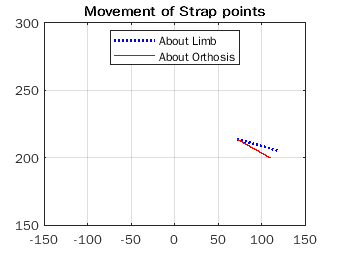

% Ankle Foot Orthosis
clc;
clear;
close all;

% All Lengths & Distances have units in "mm".
% All Angles have units in "Degrees".
% Theta in CCW direction is considered +ve and in CW direction is -ve.
% Conventions: {Anterior(->) : +ve, Posterior(<-) : -ve, Proximal(^) : +ve, Distal(v) : -ve}

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%% Inputs

% Parameters
theta = 20; % Ankle Dorsiflexion angle : -20 to 20 degrees
deltaX = -20; % Misalignment in x-direction : -20 to 20 mm
deltaY = 20; % Misalignment in y-direction : -20 to 20 mm

% Motion Type & Misalignment Type
[Limb_Motion,Misalignment_Type] = motion(theta,deltaX,deltaY);

% Limb Points (Coordinates : [x y z]': 3x1)
ACS = [0 0 1]'; % Origin (Anatomical Coordinate System)
OCS = [deltaX deltaY 1]'; % Orthosis Center (Orthotic Coordinate System)
FE = [-61.32 -63.57 1]'; % Foot End
FT = [186.44 -63.57 1]'; % Foot Tip
Knee = [0 400.98 1]'; % Knee

% Orthosis Points (Coordinates : [x y z])
TP1 = [-31.2 183.9 1]'; % Touch Point-1
TP2 = [-31.2 267.7 1]'; % Touch Point-2
SP0 = [0 233.5 1]'; % Strap Point-0
SP1 = [41.2 233.5 1]'; % Strap Point-1
FP1 = [129.5 -63.57 1]'; % Foot Point-1
FP2 = [-30.1 -63.57 1]'; % Foot Point-2
FSP0 = [39.57 -31.8 1]'; % Foot Strap Point-0
FSP1 = [86.33 2.27 1]'; % Foot Strap Point-1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%-------------------------------------------------------------------------%
%                MODEL-1 : Strap & Touch Points Movement                  %
%-------------------------------------------------------------------------%

%%%%% Computation

%%% 1.Coordinates of Points about ACS
% Here "theta" is taken "-ve" as a clock-wise movement is seen in this case
SP0_ACS = aboutACS(SP0,-theta);
SP1_ACS = aboutACS(SP1,-theta);
TP1_ACS = aboutACS(TP1,-theta);
TP2_ACS = aboutACS(TP2,-theta);
Knee_ACS = aboutACS(Knee,-theta);

%%% 2.Coordinates of Points about OCS
% Here "theta" is taken "-ve" as a clock-wise movement is seen in this case
SP0_OCS = aboutOCS(SP0,-theta,deltaX,deltaY);
SP1_OCS = aboutOCS(SP1,-theta,deltaX,deltaY);
TP1_OCS = aboutOCS(TP1,-theta,deltaX,deltaY);
TP2_OCS = aboutOCS(TP2,-theta,deltaX,deltaY);

%%% 3.Line Parameters
% Line parameters of SPs about ACS
[Distance_SP_ACS,Slope_SP_ACS,Intercept_SP_ACS] = lineParameters(SP0_OCS,SP1_ACS);
% Line parameters of SPs about OCS
[Distance_SP_OCS,Slope_SP_OCS,Intercept_SP_OCS] = lineParameters(SP0_OCS,SP1_OCS);
% Line parameters of TPs about ACS
[Distance_TP_ACS,Slope_TP_ACS,Intercept_TP_ACS] = lineParameters(TP1_ACS,TP2_ACS);
% Line parameters of TPs about OCS
[Distance_TP_OCS,Slope_TP_OCS,Intercept_TP_OCS] = lineParameters(TP1_OCS,TP2_OCS);

%-------------------------------------------------------------------------%

%%%%% Results

% 1.1 Direction of Calf Band Travel w.r.t Direction of Ankle Motion
Calf_Band_Travel = strapMovement(Distance_SP_ACS,Distance_SP_OCS,Slope_SP_ACS,Slope_SP_OCS);

% 1.2 Anterior-Posterior & Proximal-Distal Relative Motions (in mm)
[AP_SP,PD_SP] = relativeMotionSP(SP0_OCS,SP1_ACS,SP1_OCS,Distance_SP_ACS,Distance_SP_OCS,Slope_SP_ACS,Slope_SP_OCS);

% 1.3 Strap Points movement illustration plot
illustrationPlotSP(SP0_OCS,SP1_ACS,SP1_OCS,[-150,150],[150,300],'Strap');

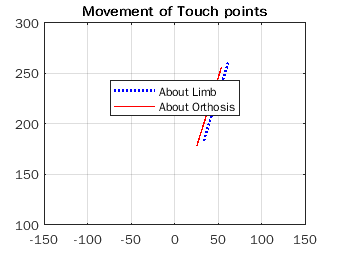


% 1.4 Resulant Pressure On Leg
Res_Pressure_Leg = pressurePointLeg(theta,Intercept_TP_ACS,Intercept_TP_OCS);

% 1.5 Anterior-Posterior & Proximal-Distal Relative Motions (in mm)
[AP_TP,PD_TP] = relativeMotionTP(TP1_ACS,TP2_ACS,TP2_OCS,theta,Intercept_TP_ACS,Intercept_TP_OCS);

% 1.6 Touch Points movement illustration plot
illustrationPlotP(TP1_ACS,TP2_ACS,TP1_OCS,TP2_OCS,[-150,150],[100,300],'Touch');

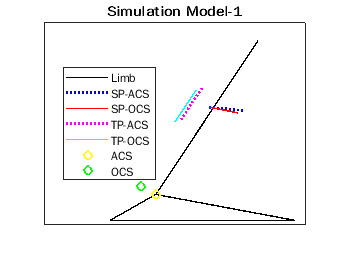


%-------------------------------------------------------------------------%

%%%%% Simulation Model
figure;
plot([ACS(1),FE(1)],[ACS(2),FE(2)],'k-','LineWidth',1)
hold on;
plot([ACS(1),FT(1)],[ACS(2),FT(2)],'k-','LineWidth',1)
plot([ACS(1),Knee_ACS(1)],[ACS(2),Knee_ACS(2)],'k-','LineWidth',1)
plot([FT(1),FE(1)],[FT(2),FE(2)],'k-','LineWidth',1)
plot([SP0_OCS(1),SP1_ACS(1)],[SP0_OCS(2),SP1_ACS(2)],'b:','LineWidth',2)
plot([SP0_OCS(1),SP1_OCS(1)],[SP0_OCS(2),SP1_OCS(2)],'r-','LineWidth',1)
plot([TP1_ACS(1),TP2_ACS(1)],[TP1_ACS(2),TP2_ACS(2)],'m:','LineWidth',2)
plot([TP1_OCS(1),TP2_OCS(1)],[TP1_OCS(2),TP2_OCS(2)],'c-','LineWidth',1)
plot(ACS(1),ACS(2),'yo','LineWidth',1.5)
plot(OCS(1),OCS(2),'go','LineWidth',1.5)
title('Simulation Model-1')
xlim([-150,200]),ylim([-75,420])
xticks([]),yticks([]);
legend('Limb','','','','SP-ACS','SP-OCS','TP-ACS','TP-OCS','ACS','OCS',"Location","best")
hold off;

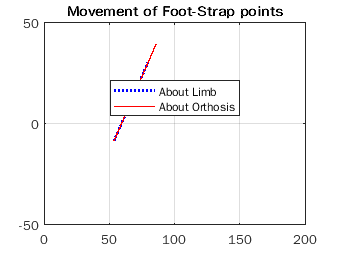


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%-------------------------------------------------------------------------%
%              MODEL-2 : Foot-Strap & Foot Points Movement                %
%-------------------------------------------------------------------------%

%%%%% Computation

%%% 1.Coordinates of Points about ACS
% Here "theta" is taken "+ve" as a CCW movement is seen in this case
FP1_ACS = aboutACS(FP1,theta);
FP2_ACS = aboutACS(FP2,theta);
FSP0_ACS = aboutACS(FSP0,theta);
FSP1_ACS = aboutACS(FSP1,theta);
FE_ACS = aboutACS(FE,theta);
FT_ACS = aboutACS(FT,theta);

%%% 2.Coordinates of Points about OCS
% Here "theta" is taken "+ve" as a CCW movement is seen in this case
FP1_OCS = aboutOCS(FP1,theta,deltaX,deltaY);
FP2_OCS = aboutOCS(FP2,theta,deltaX,deltaY);
FSP0_OCS = aboutOCS(FSP0,theta,deltaX,deltaY);
FSP1_OCS = aboutOCS(FSP1,theta,deltaX,deltaY);

%%% 3.Line Parameters
% Line parameters of FPs about ACS
[Distance_FP_ACS,Slope_FP_ACS,Intercept_FP_ACS] = lineParameters(FP1_ACS,FP2_ACS);
% Line parameters of FPs about OCS
[Distance_FP_OCS,Slope_FP_OCS,Intercept_FP_OCS] = lineParameters(FP1_OCS,FP2_OCS);
% Line parameters of FSPs about ACS
[Distance_FSP_ACS,Slope_FSP_ACS,Intercept_FSP_ACS] = lineParameters(FSP0_OCS,FSP1_ACS);
% Line parameters of FSPs about OCS
[Distance_FSP_OCS,Slope_FSP_OCS,Intercept_FSP_OCS] = lineParameters(FSP0_OCS,FSP1_OCS);

%-------------------------------------------------------------------------%

%%%%% Results

% 2.1 Foot Strap Movement
Foot_Strap_Movement = strapMovement(Distance_FSP_ACS,Distance_FSP_OCS,Slope_FSP_ACS,Slope_FSP_OCS);

% 2.2 Anterior-Posterior & Proximal-Distal Relative Motions (in mm)
[AP_FSP,PD_FSP] = relativeMotionSP(FSP0_OCS,FSP1_ACS,FSP1_OCS,Distance_FSP_ACS,Distance_FSP_OCS,Slope_FSP_ACS,Slope_FSP_OCS);

% 2.3 Strap Points movement illustration plot
illustrationPlotSP(FSP0_OCS,FSP1_ACS,FSP1_OCS,[0,200],[-75 50],'Foot-Strap');

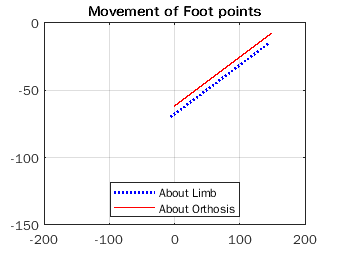


% 2.4 Resulant Pressure On Feet
Res_Pressure_Feet = pressurePointFeet(Intercept_FP_ACS,Intercept_FP_OCS);

% 2.5 Anterior-Posterior & Proximal-Distal Relative Motions (in mm)
[AP_FP,PD_FP] = relativeMotionFP(FP1_ACS,FP2_ACS,FP1_OCS,FP2_OCS,Slope_FP_ACS,Intercept_FP_ACS,Intercept_FP_OCS);

% 2.6 Foot Points movement illustration plot
illustrationPlotP(FP1_ACS,FP2_ACS,FP1_OCS,FP2_OCS,[-200,200],[-150,0],'Foot');

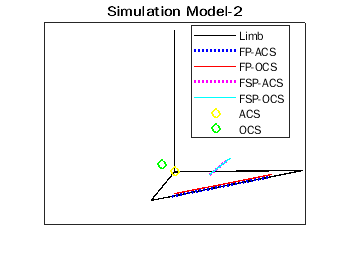


%-------------------------------------------------------------------------%

%%%%% Simulation Model
figure;
plot([ACS(1),Knee(1)],[ACS(2),Knee(2)],'k-','LineWidth',1)
hold on;
plot([ACS(1),FE_ACS(1)],[ACS(2),FE_ACS(2)],'k-','LineWidth',1)
plot([ACS(1),FT_ACS(1)],[ACS(2),FT_ACS(2)],'k-','LineWidth',1)
plot([FE_ACS(1),FT_ACS(1)],[FE_ACS(2),FT_ACS(2)],'k-','LineWidth',1)
plot([FP1_ACS(1),FP2_ACS(1)],[FP1_ACS(2),FP2_ACS(2)],'b:','LineWidth',2)
plot([FP1_OCS(1),FP2_OCS(1)],[FP1_OCS(2),FP2_OCS(2)],'r-','LineWidth',1)
plot([FSP0_OCS(1),FSP1_ACS(1)],[FSP0_OCS(2),FSP1_ACS(2)],'m:','LineWidth',2)
plot([FSP0_OCS(1),FSP1_OCS(1)],[FSP0_OCS(2),FSP1_OCS(2)],'c-','LineWidth',1)
plot(ACS(1),ACS(2),'yo','LineWidth',1.5)
plot(OCS(1),OCS(2),'go','LineWidth',1.5)
xlim([-200 200]),ylim([-150 420])
title('Simulation Model-2')
xticks([]),yticks([]);
legend('Limb','','','','FP-ACS','FP-OCS','FSP-ACS','FSP-OCS','ACS','OCS',"Location","best")
hold off;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%% Outputs
disp(['Misalignment Type : ',Misalignment_Type])

Misalignment Type : Posterior Proximal


disp(['Limb Motion : ',Limb_Motion])

Limb Motion : Dorsiflexion


disp(['A-P relative motion of SPs : ',num2str(AP_SP),' mm.'])

A-P relative motion of SPs : -5.6343 mm.


disp(['P-D relative motion of SPs : ',num2str(PD_SP),' mm.'])

P-D relative motion of SPs : -8.0466 mm.


disp(['Calf Band Travel : ',Calf_Band_Travel])

Calf Band Travel : Posterior Distal


disp(['A-P relative motion of TPs : ',num2str(AP_TP),' mm.'])

A-P relative motion of TPs : -5.6343 mm.


disp(['P-D relative motion of TPs : ',num2str(PD_TP),' mm.'])

P-D relative motion of TPs : -8.0466 mm.


disp(['Resultant Pressure Point on Leg : ',Res_Pressure_Leg])

Resultant Pressure Point on Leg : Anterior


disp(['A-P relative motion of FSPs : ',num2str(AP_FSP),' mm.'])

A-P relative motion of FSPs : 9.8213 mm.


disp(['P-D relative motion of FSPs : ',num2str(PD_FSP),' mm.'])

P-D relative motion of FSPs : -0.18474 mm.


disp(['Foot Strap Movement : ',Foot_Strap_Movement])

Foot Strap Movement : Anterior Distal


disp(['A-P relative motion of FPs : ',num2str(AP_FP),' mm.'])

A-P relative motion of FPs : 8.0466 mm.


disp(['P-D relative motion of FPs : ',num2str(PD_FP),' mm.'])

P-D relative motion of FPs : 5.6343 mm.


disp(['Resultant Pressure Point on Feet : ',Res_Pressure_Feet])

Resultant Pressure Point on Feet : Distal-Bottom



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%-------------------------------------------------------------------------%
%                          DEFINED FUNCTIONS                              %
%-------------------------------------------------------------------------%

% Function for determining Motion & Misalignment Type

function [Limb_Motion,Misalignment_Type] = motion(theta,deltaX,deltaY)
    % Limb Motion with reference to Ankle Dorsiflexion angle
    if theta<0
        Limb_Motion = 'Plantar flexion';
    elseif theta>0
        Limb_Motion = 'Dorsiflexion';
    else
        Limb_Motion = 'Neutral';
    end
    
    % Misalignment type with reference to deltaX
    if deltaX>0
        X_Misalignment = 'Anterior';
    elseif deltaX<0
        X_Misalignment = 'Posterior';
    else
        X_Misalignment = '';
    end
    
    % Misalignment type with reference to deltaY
    if deltaY>0
        Y_Misalignment = 'Proximal';
    elseif deltaY<0
        Y_Misalignment = 'Distal';
    else
        Y_Misalignment = '';
    end
    
    % Misalignment type with reference to deltaX & deltaY
    if strlength(X_Misalignment)==0 && strlength(Y_Misalignment)==0
        Misalignment_Type = 'None';
    else
        Misalignment_Type = [X_Misalignment,' ',Y_Misalignment];
    end
end

%-------------------------------------------------------------------------%

% Function for computing coordinates of points about ACS
function P_ACS = aboutACS(P,theta)

% Rotation Matrix
    R = [cosd(theta) -sind(theta) 0;
        sind(theta) cosd(theta) 0;
        0 0 1];
    P_ACS = R*P; % Point "P" rotated about ACS

end

%-------------------------------------------------------------------------%

% Function for computing coordinates of points about OCS
function P_OCS = aboutOCS(P,theta,deltaX,deltaY)

% Rotation Matrix
R = [cosd(theta) -sind(theta) 0;
    sind(theta) cosd(theta) 0;
    0 0 1];
% Translation / Shift Matrix
T = [1 0 deltaX;
    0 1 deltaY;
    0 0 1];

P_trans = T\P; % Point "P" translated to OCS
P_ortho = R*P_trans; % Point "P" rotated about Orthosis axis
P_OCS = T*P_ortho; % Point "P" translated back to ACS; Mentioned as OCS for ease

end

%-------------------------------------------------------------------------%

% Function for determining line parameters
function [D,S,I] = lineParameters(P1,P2)
    D = sqrt((P1(1)-P2(1))^2 + (P1(2)-P2(2))^2 + (P1(3)-P2(3))^2); % Distance
    S = (P2(2)-P1(2))/(P2(1)-P1(1)); % Slope
    I = P1(2)-S*P1(1); % Intercept
end

%-------------------------------------------------------------------------%

% Function for determining Strap Movement
function SM = strapMovement(D1,D2,S1,S2)
    % Horizontal Separation
    if D1<D2
        SM_H = 'Anterior';
    elseif D1>D2
        SM_H = 'Posterior';
    else
        SM_H = '';
    end
    % Vertical Separation
    if S1>S2
        SM_V = 'Distal';
    elseif S1<S2
        SM_V = 'Proximal';
    else
        SM_V = '';
    end
    SM = [SM_H,' ',SM_V];
end

%-------------------------------------------------------------------------%

% Function for A-P & P-D Relative Motions for Strap & Foot Strap Points
function [AP,PD] = relativeMotionSP(P0_OCS,P1_ACS,P1_OCS,D1,D2,S1,S2)
    MSP = P1_ACS; % Moving Strap Point
    length_P1s = sqrt((P1_ACS(1)-P1_OCS(1))^2+(P1_ACS(2)-P1_OCS(2))^2);
    A = P0_OCS(2)-P1_OCS(2);
    B = P1_OCS(1)-P0_OCS(1);
    C = P0_OCS(1)*P1_OCS(2)-P1_OCS(1)*P0_OCS(2);
    pd = abs((A*MSP(1)+B*MSP(2)+C)/sqrt(A^2 + B^2));
    ap = sqrt(length_P1s^2 - pd^2);
    % Sign convention for Relative Motions
    % Horizontal Separation
    if D1<=D2
        AP = ap;
    elseif D1>D2
        AP = -ap;
    end
    % Vertical Separation
    if S1>S2
        PD = -pd;
    elseif S1<=S2
        PD = pd;
    end
end

%-------------------------------------------------------------------------%

% Function for A-P & P-D Relative Motions for Touch Points
function [AP,PD] = relativeMotionTP(P1_ACS,P2_ACS,P2_OCS,theta,I1,I2)
    P = P2_OCS;
    length_P2s = sqrt((P2_ACS(1)-P2_OCS(1))^2+(P2_ACS(2)-P2_OCS(2))^2);
    A = P1_ACS(2)-P2_ACS(2);
    B = P2_ACS(1)-P1_ACS(1);
    C = P1_ACS(1)*P2_ACS(2)-P2_ACS(1)*P1_ACS(2);
    ap = abs((A*P(1)+B*P(2)+C)/sqrt(A^2 + B^2));
    pd = sqrt(length_P2s^2 - ap^2);
    % Sign convention for Relative Motions
    % Vertical Separation
    if P2_ACS(2)>P2_OCS(2)
        PD = -pd;
    elseif P2_ACS(2)<=P2_OCS(2)
        PD = pd;
    end
    % Horizontal Separation
    if theta<0
        if I1>I2
            AP = -ap;
        elseif I1<I2
            AP = ap;
        else
            AP = ap;
        end
    elseif theta>0
        if I1<I2
            AP = -ap;
        elseif I1>I2
            AP = ap;
        else
            AP = ap;
        end
    else
        PD = 0;
        AP = 0;
    end
end

%-------------------------------------------------------------------------%

% Function for A-P & P-D Relative Motions for Foot Points
function [AP,PD] = relativeMotionFP(P1_ACS,P2_ACS,P1_OCS,P2_OCS,S,I1,I2)
    P = P2_OCS;
    length_P2s = sqrt((P2_ACS(1)-P2_OCS(1))^2+(P2_ACS(2)-P2_OCS(2))^2);
    A = P1_ACS(2)-P2_ACS(2);
    B = P2_ACS(1)-P1_ACS(1);
    C = P1_ACS(1)*P2_ACS(2)-P2_ACS(1)*P1_ACS(2);
    pd = abs((A*P(1)+B*P(2)+C)/sqrt(A^2 + B^2));
    ap = sqrt(length_P2s^2 - pd^2);
    % Sign convention for Relative Motions
    % Vertical Separation
    if I1>I2
        PD = -pd;
    elseif I1<I2
        PD = pd;
    else
        PD = pd;
    end
    % Horizontal Separation
    % Intercepts of perpendicular lines
    IP1 = P1_ACS(2) + (P1_ACS(1)/S);
    IP2 = P1_OCS(2) + (P1_OCS(1)/S);
    % Points on x-axis where the perpendicular lines intersect x-axis
    X1 = S*IP1;
    X2 = S*IP2;
    if X1>X2
        AP = -ap;
    elseif X1<X2
        AP = ap;
    else
        AP = ap;
    end
end

%-------------------------------------------------------------------------%

% Function for illustration plots of Strap & Foot-strap points
function illustrationPlotSP(P0_OCS,P1_ACS,P1_OCS,XLim,YLim,points)

    figure;
    plot([P0_OCS(1),P1_ACS(1)],[P0_OCS(2),P1_ACS(2)],'b:','LineWidth',2)
    hold on;
    plot([P0_OCS(1),P1_OCS(1)],[P0_OCS(2),P1_OCS(2)],'r-','LineWidth',1)
    xlim(XLim),ylim(YLim)
    title(['Movement of ',points,' points'])
    grid on;
    legend('About Limb','About Orthosis',"Location","best")
    hold off;

end

%-------------------------------------------------------------------------%

% Function for illustration plots of Foot & Touch points
function illustrationPlotP(P1_ACS,P2_ACS,P1_OCS,P2_OCS,XLim,YLim,points)

    figure;
    plot([P1_ACS(1),P2_ACS(1)],[P1_ACS(2),P2_ACS(2)],'b:','LineWidth',2)
    hold on;
    plot([P1_OCS(1),P2_OCS(1)],[P1_OCS(2),P2_OCS(2)],'r-','LineWidth',1)
    xlim(XLim),ylim(YLim)
    title(['Movement of ',points,' points'])
    grid on;
    legend('About Limb','About Orthosis',"Location","best")
    hold off;

end

%-------------------------------------------------------------------------%

% Resultant Pressure Point on Leg
function Res_Pressure = pressurePointLeg(theta,I1,I2)
    if theta<0
        if I1>I2
            Res_Pressure = 'Anterior';
        elseif I1<I2
            Res_Pressure = 'Posterior';
        else
            Res_Pressure = 'None';
        end
    elseif theta>0
        if I1<I2
            Res_Pressure = 'Anterior';
        elseif I1>I2
            Res_Pressure = 'Posterior';
        else
            Res_Pressure = 'None';
        end
    else
        Res_Pressure = 'None';
    end
end

%-------------------------------------------------------------------------%

% Resultant Pressure Point on Feet
function Res_Pressure = pressurePointFeet(I1,I2)
    if I1>I2
        Res_Pressure = 'Proximal-Top';
    elseif I1<I2
        Res_Pressure = 'Distal-Bottom';
    else
        Res_Pressure = 'None';
    end
end